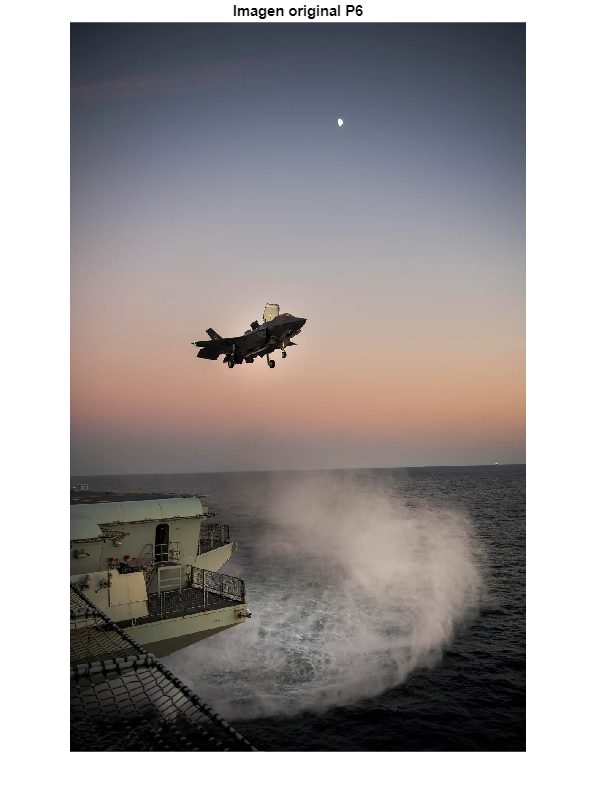

%% 1. Cargar y representar la imagen
clear; close all; clc;

img = imread('P6.jpg');
figure; imshow(img); title('Imagen original P6');


fprintf('Tamaño: %d × %d px\n', size(img,1), size(img,2));

Tamaño: 1728 × 1080 px


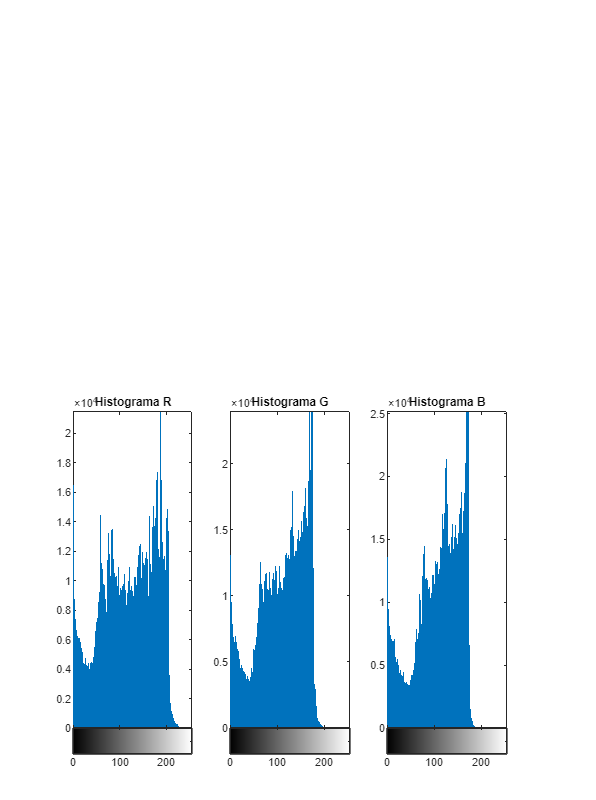


% Histogramas RGB
figure;
subplot(1,3,1); imhist(img(:,:,1)); title('Histograma R');
subplot(1,3,2); imhist(img(:,:,2)); title('Histograma G');
subplot(1,3,3); imhist(img(:,:,3)); title('Histograma B');

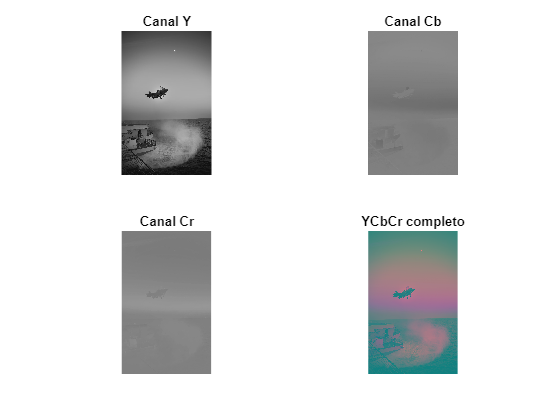

%% 2. Conversión a YCbCr
img_ycbcr = rgb2ycbcr(img);

figure;
subplot(2,2,1); imshow(img_ycbcr(:,:,1)); title('Canal Y');
subplot(2,2,2); imshow(img_ycbcr(:,:,2)); title('Canal Cb');
subplot(2,2,3); imshow(img_ycbcr(:,:,3)); title('Canal Cr');
subplot(2,2,4); imshow(img_ycbcr); title('YCbCr completo');

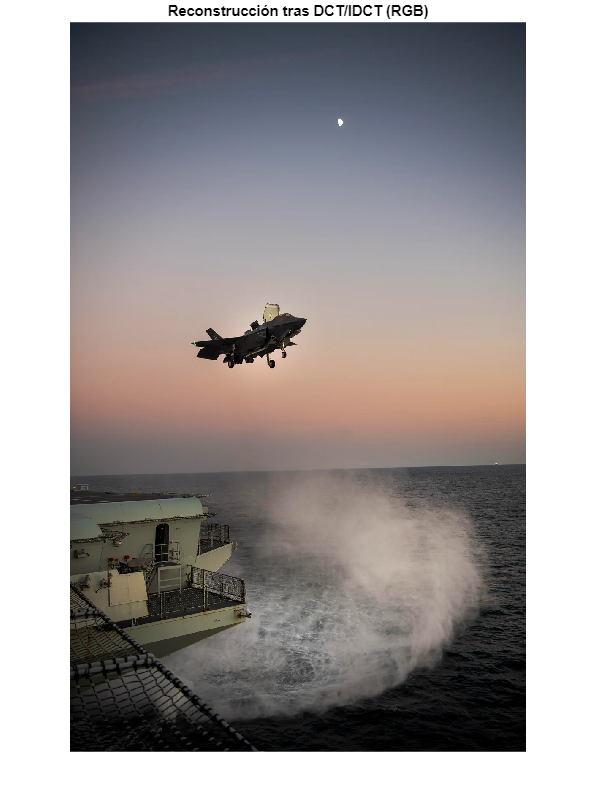

%% 3. DCT por bloques (8x8) y reconstrucción

img_d = double(img_ycbcr);

fun_dct  = @(block) dct2(block.data);
fun_idct = @(block) idct2(block.data);

% DCT canal por canal
Y_dct  = blockproc(img_d(:,:,1), [8 8], fun_dct);
Cb_dct = blockproc(img_d(:,:,2), [8 8], fun_dct);
Cr_dct = blockproc(img_d(:,:,3), [8 8], fun_dct);

% Reconstrucción
Y_rec  = blockproc(Y_dct,  [8 8], fun_idct);
Cb_rec = blockproc(Cb_dct, [8 8], fun_idct);
Cr_rec = blockproc(Cr_dct, [8 8], fun_idct);

img_dct_rec = cat(3, Y_rec, Cb_rec, Cr_rec);

% CONVERSIÓN CORRECTA A RGB (sino se ve raro)
img_dct_rec_rgb = ycbcr2rgb(uint8(img_dct_rec));

figure; imshow(img_dct_rec_rgb);
title('Reconstrucción tras DCT/IDCT (RGB)');

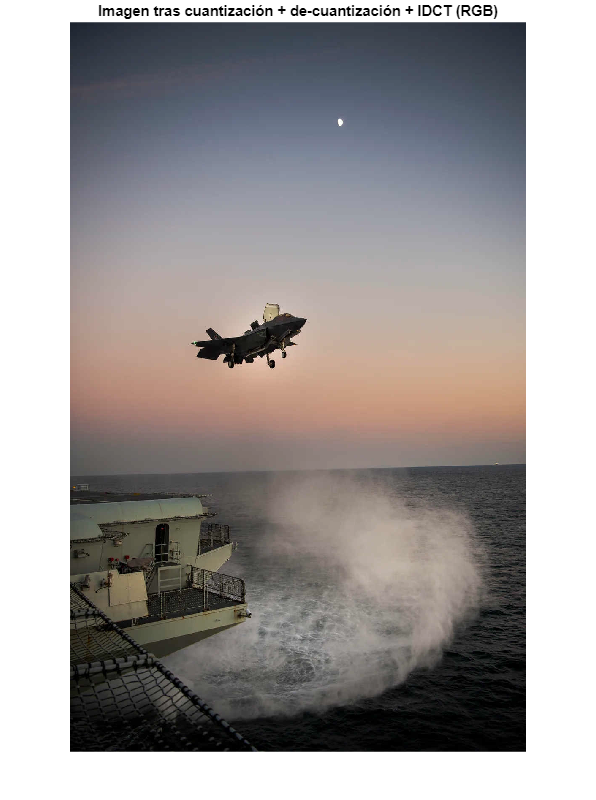

%% 4. Cuantización + De-cuantización

Q = [
    16 11 10 16 24 40 51 61;
    12 12 14 19 26 48 60 55;
    14 13 16 24 40 57 69 56;
    14 17 22 29 51 87 80 62;
    18 22 37 56 68 109 103 77;
    24 35 55 64 81 104 113 92;
    49 64 78 87 103 121 120 101;
    72 92 95 98 112 100 103 99];

fun_quant   = @(block) round(block.data ./ Q);
fun_dequant = @(block) block.data .* Q;

% Cuantización
Y_q  = blockproc(Y_dct,  [8 8], fun_quant);
Cb_q = blockproc(Cb_dct, [8 8], fun_quant);
Cr_q = blockproc(Cr_dct, [8 8], fun_quant);

% De-cuantización
Y_dq  = blockproc(Y_q,  [8 8], fun_dequant);
Cb_dq = blockproc(Cb_q, [8 8], fun_dequant);
Cr_dq = blockproc(Cr_q, [8 8], fun_dequant);

% Reconstrucción IDCT
Y_idct  = blockproc(Y_dq,  [8 8], fun_idct);
Cb_idct = blockproc(Cb_dq, [8 8], fun_idct);
Cr_idct = blockproc(Cr_dq, [8 8], fun_idct);

img_dequant = cat(3, Y_idct, Cb_idct, Cr_idct);

% CONVERSIÓN A RGB
img_dequant_rgb = ycbcr2rgb(uint8(img_dequant));

figure;
imshow(img_dequant_rgb);
title('Imagen tras cuantización + de-cuantización + IDCT (RGB)');

function zz = zigzag8x8(block)
    order = [
         1  2  6  7 15 16 28 29
         3  5  8 14 17 27 30 43
         4  9 13 18 26 31 42 44
        10 12 19 25 32 41 45 54
        11 20 24 33 40 46 53 55
        21 23 34 39 47 52 56 61
        22 35 38 48 51 57 60 62
        36 37 49 50 58 59 63 64];

    zz = block(order);
end


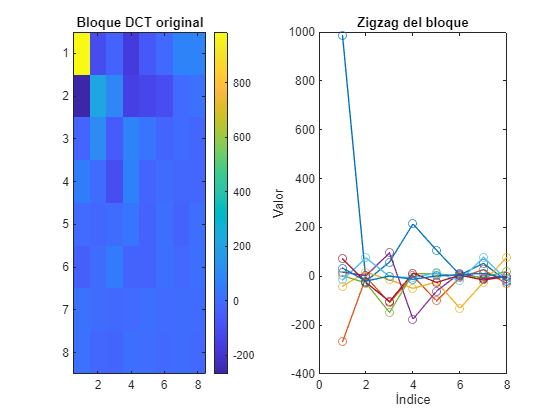

%% 5. Zigzag con función propia (corregido de verdad)

%% Seleccionamos automáticamente un bloque con detalles fuertes

% calculamos energía de cada bloque
energias = zeros(floor(size(Y_dct,1)/8), floor(size(Y_dct,2)/8));

for i = 1:8:size(Y_dct,1)
    for j = 1:8:size(Y_dct,2)
        bloque_tmp = Y_dct(i:i+7, j:j+7);
        energias((i+7)/8, (j+7)/8) = sum(abs(bloque_tmp(:)));
    end
end

% tomamos el bloque con mayor energía (mucho detalle)
[maxE, idx] = max(energias(:));
[f_i, c_i] = ind2sub(size(energias), idx);

fila = (f_i-1)*8 + 1;
col  = (c_i-1)*8 + 1;

bloque = Y_dct(fila:fila+7, col:col+7);
zig = zigzag8x8(bloque);


figure;
subplot(1,2,1);
imagesc(bloque); colorbar;
title('Bloque DCT original');

subplot(1,2,2);
plot(zig, '-o');
title('Zigzag del bloque');
xlabel('Índice'); ylabel('Valor');


fprintf("Longitud zigzag: %d elementos\n", length(zig));

Longitud zigzag: 8 elementos


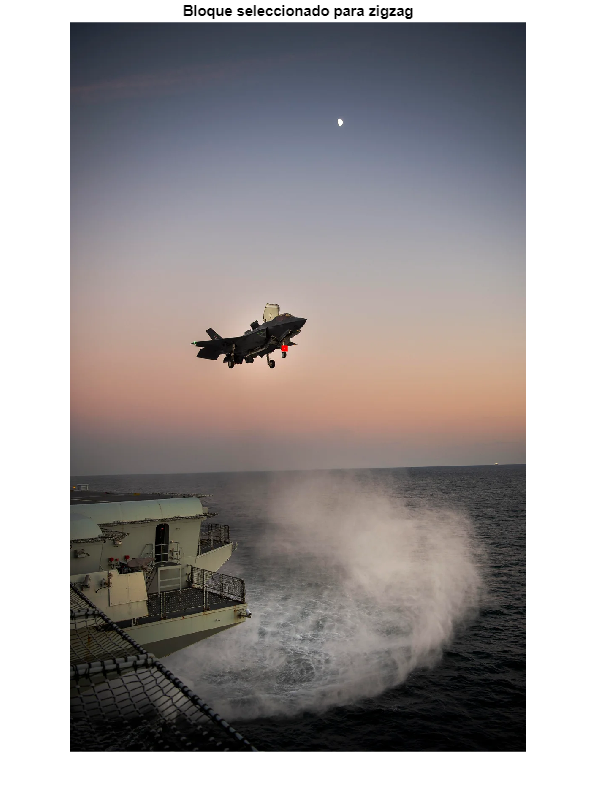

%% Mostrar el bloque seleccionado en la imagen original
figure;
imshow(img);
hold on;

% Dibujar un rectángulo alrededor del bloque (en rojo)
rectangle('Position',[col, fila, 8, 8], 'EdgeColor','r', 'LineWidth',2);

title('Bloque seleccionado para zigzag');
hold off;

%% 6. CODIFICACIÓN ENTROPÍA — OPTIMIZADO

% --- 6.1 DC: DPCM ---
DC_vals = Y_q(1:8:end,1:8:end);
DC_vec = DC_vals(:);
DC_diff = [DC_vec(1); diff(DC_vec)];

% DC Huffman (mucho más rápido con celdas)
DC_tmp = cell(length(DC_diff),1);
for n = 1:length(DC_diff)
    DC_tmp{n} = huffman_dc(DC_diff(n));
end
DC_bin = strjoin(DC_tmp','');

% --- 6.2 Vector AC usando zigzag ---
AC_vec = [];
for i = 1:8:size(Y_q,1)
    for j = 1:8:size(Y_q,2)
        block = Y_q(i:i+7, j:j+7);
        zz = zigzag8x8(block);
        AC_vec = [AC_vec zz(2:end)];
    end
end

% AC Huffman optimizado
AC_tmp = cell(length(AC_vec),1);
for n = 1:length(AC_vec)
    AC_tmp{n} = huffman_ac(AC_vec(n));
end
AC_bin = strjoin(AC_tmp','');

% Tamaño final
total_bits = length(DC_bin) + length(AC_bin);

fprintf("Tamaño final tras Huffman: %d bits\n", total_bits);

Tamaño final tras Huffman: 7678778 bits


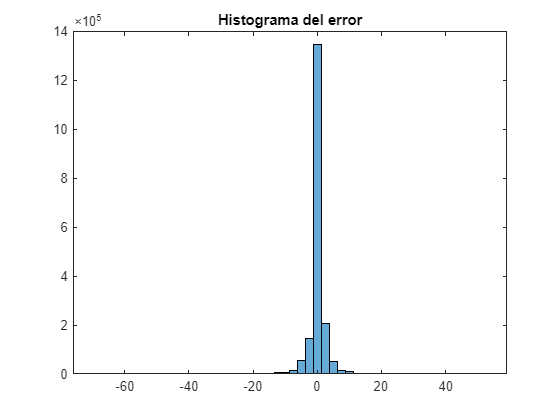

%% 7. Error respecto a la imagen original

img_dec = img_dequant_rgb;
err = double(rgb2gray(img)) - double(rgb2gray(img_dec));

figure; histogram(err(:), 50);
title('Histograma del error');

%% 8. Relación de compresión

bits_orig = numel(img) * 8;
Rc = bits_orig / total_bits;

fprintf("Relación de compresión Rc = %.3f\n", Rc);

Relación de compresión Rc = 5.833


%% 9. Calidad: MSE, PSNR, SNR

img_d = double(img);
img_r = double(img_dec);

mse = mean((img_d(:) - img_r(:)).^2);
psnr_val = 10*log10(255^2 / mse);
snr_val = 10*log10(mean(img_d(:).^2) / mse);

fprintf("MSE = %.4f\n", mse);

MSE = 8.5757


fprintf("PSNR = %.2f dB\n", psnr_val);

PSNR = 38.80 dB


fprintf("SNR  = %.2f dB\n", snr_val);

SNR  = 32.54 dB
